clear; close all; clc;

%% -------------------- Paths --------------------
load ("D:\Hippocampus Paper\HistCenterTime.mat");   % time vector (1 x T)
% L5 is CA1 for convinience
load("D:\V1_Cortex_Paper\MultichannelDataTanks\GranAverage\Layers\F1F2_matrices_L_5_V1.mat")
DEV_F1_F2_CA1 = F1F2.DEV_F1_F2;
STD_F1_F2_CA1 = F1F2.STD_F1_F2;

% L6 is DG for convinience
load("D:\V1_Cortex_Paper\MultichannelDataTanks\GranAverage\Layers\F1F2_matrices_L_6_V1.mat")
DEV_F1_F2_DG = F1F2.DEV_F1_F2;
STD_F1_F2_DG = F1F2.STD_F1_F2;

t = HistCentersTime(:)';   % enforce row

%% -------------------- MMN per region --------------------
MMN_CA1 = DEV_F1_F2_CA1 - STD_F1_F2_CA1;   % [C1 x T]
MMN_DG  = DEV_F1_F2_DG  - STD_F1_F2_DG;    % [C2 x T]

% Means and SEMs across channels
[mu_CA1, sem_CA1] = mean_sem(MMN_CA1, 1);
[mu_DG,  sem_DG ] = mean_sem(MMN_DG,  1);

%% -------------------- Per-time Welch t-test: CA1 vs DG (MMN) --------------------
% Two-sample Welch t-test at each time bin
nT = numel(t);
p  = nan(1,nT);
h  = false(1,nT);
d  = nan(1,nT);      % Cohen's d (pooled SD) for info
for k = 1:nT
    x = MMN_CA1(:,k); x = x(~isnan(x));
    y = MMN_DG(:,k);  y = y(~isnan(y));
    if numel(x) >= 3 && numel(y) >= 3 && any(x~=0) || any(y~=0)
        [~,p(k)] = ttest2(x, y, 'Vartype','unequal');  % Welch
        d(k)     = cohend(x, y);
    end
end

% Benjamini-Hochberg FDR (q = 0.05)
q = 0.05;
[h_fdr, p_fdr] = fdr_bh(p, q);

fprintf('\n=== MMN L5 vs L6 (per time bin) ===\n');


=== MMN L5 vs L6 (per time bin) ===


fprintf('FDR q = %.3f. Significant bins: %d / %d\n', q, sum(h_fdr), nT);

FDR q = 0.050. Significant bins: 1 / 40



%% -------------------- Plot MMN with significance overlay --------------------
figure('Color','w'); hold on;
% Mean ± SEM
shadedErrorBar(t, mu_CA1, sem_CA1, 'lineProps', {'b','LineWidth',1.8});
shadedErrorBar(t, mu_DG,  sem_DG,  'lineProps', {'r','LineWidth',1.8});
yline(0,'k:');

% Significance ribbon (bottom line where h_fdr==1)
yl = ylim;
sig_y = yl(1) + 0.05*range(yl);
plot(t, nanmask(h_fdr, sig_y), 'k', 'LineWidth', 3);
legend({'L5 MMN','', 'L6 MMN','', '0', 'FDR-significant'}, 'Location','best');

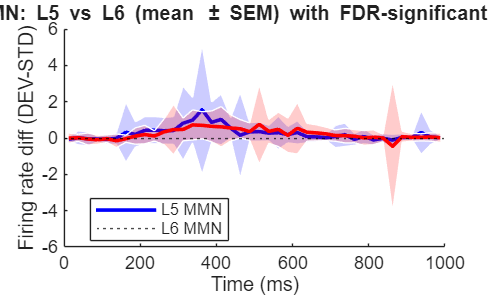

xlabel('Time (ms)'); ylabel('Firing rate diff (DEV-STD)');
title('MMN: L5 vs L6 (mean \pm SEM) with FDR-significant bins');

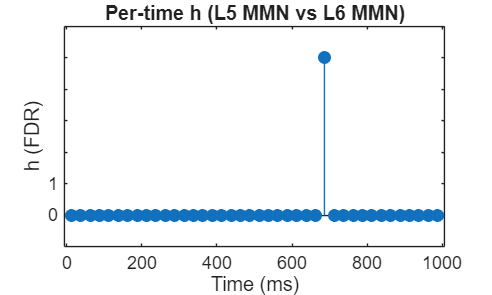


% Optional: binary h plot
figure('Color','w'); 
stem(t, double(h_fdr), 'filled');
ylim([-0.2 1.2]); yticklabels({'','0','1'});
xlabel('Time (ms)'); ylabel('h (FDR)'); title('Per-time h (L5 MMN vs L6 MMN)');


%% -------------------- Consecutive-2 half-max onset (DEV & STD) --------------------
run_len       = 2;           % consecutive-2
post_onset_ms = 0;           % search from 0 ms
base_win_ms   = [-50 0];     % baseline window

% Build baseline mask from t
if any(t >= base_win_ms(1) & t <= base_win_ms(2))
    base_mask = t >= base_win_ms(1) & t <= base_win_ms(2);
else
    base_mask = false(size(t));
    idx = 5:min(8,numel(t)); base_mask(idx) = true;
end

% Onsets
lat_DEV_CA1 = halfmax_consecutive_latency(DEV_F1_F2_CA1, t, base_mask, post_onset_ms, run_len);
lat_STD_CA1 = halfmax_consecutive_latency(STD_F1_F2_CA1, t, base_mask, post_onset_ms, run_len);
lat_DEV_DG  = halfmax_consecutive_latency(DEV_F1_F2_DG,  t, base_mask, post_onset_ms, run_len);
lat_STD_DG  = halfmax_consecutive_latency(STD_F1_F2_DG,  t, base_mask, post_onset_ms, run_len);

%% -------- Region comparisons: DEV L5 vs DEV L6, STD L5 vs STD L6 --------
stats_region = struct();

% Unpaired comparisons across regions (different channels)
stats_region.DEV = best_group_test(lat_DEV_CA1, lat_DEV_DG, 'DEV: L5 vs L6');


[Rank-sum] DEV: L5 vs L6: h=0, p=0.9702, effect Cliffs_delta=0.018


stats_region.STD = best_group_test(lat_STD_CA1, lat_STD_DG, 'STD: L5 vs L6');


[Rank-sum] STD: L5 vs L6: h=0, p=0.347, effect Cliffs_delta=0.280



%% -------- Console summary --------
fprintf('\n=== Region comparisons (onset latencies) ===\n');


=== Region comparisons (onset latencies) ===


fprintf('DEV: test=%s, h=%d, p=%.4g, effect=%s=%.3f\n', ...
    stats_region.DEV.test, stats_region.DEV.h, stats_region.DEV.p, ...
    stats_region.DEV.effect_name, stats_region.DEV.effect);

DEV: test=Rank-sum, h=0, p=0.9702, effect=Cliffs_delta=0.018



fprintf('STD: test=%s, h=%d, p=%.4g, effect=%s=%.3f\n', ...
    stats_region.STD.test, stats_region.STD.h, stats_region.STD.p, ...
    stats_region.STD.effect_name, stats_region.STD.effect);

STD: test=Rank-sum, h=0, p=0.347, effect=Cliffs_delta=0.280



fprintf('\nGroup summaries (mean ± SEM, n)\n');


Group summaries (mean ± SEM, n)


summ_line('DEV L5', lat_DEV_CA1);

DEV L5 : 327.155 ± 83.055 (SEM), n=29


summ_line('DEV L6 ', lat_DEV_DG );

DEV L6 : 318.269 ± 62.307 (SEM), n=65


summ_line('STD L5', lat_STD_CA1);

STD L5 : 375.000 ± 118.673 (SEM), n=16


summ_line('STD L6 ', lat_STD_DG );

STD L6 : 320.357 ± 237.463 (SEM), n=35


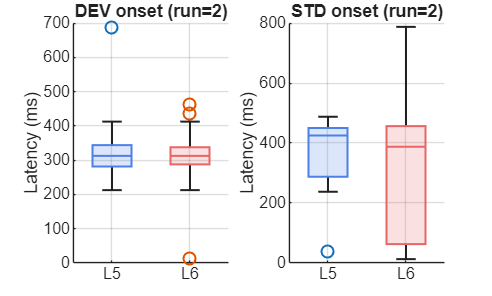


%% -------- Plots --------
figure('Color','w'); 
subplot(1,2,1);
boxchart_grouped(lat_DEV_CA1, lat_DEV_DG, {'L5','L6'});
ylabel('Latency (ms)'); title(sprintf('DEV onset (run=%d)', run_len));

subplot(1,2,2);
boxchart_grouped(lat_STD_CA1, lat_STD_DG, {'L5','L6'});
ylabel('Latency (ms)'); title(sprintf('STD onset (run=%d)', run_len));


fprintf('\n=== Consecutive-%d half-max onsets (ms, mean ± SEM) ===\n', run_len);


=== Consecutive-2 half-max onsets (ms, mean ± SEM) ===


summ_line('DEV  L5', lat_DEV_CA1);

DEV  L5: 327.155 ± 83.055 (SEM), n=29


summ_line('DEV  L6 ', lat_DEV_DG );

DEV  L6 : 318.269 ± 62.307 (SEM), n=65


summ_line('STD  L5', lat_STD_CA1);

STD  L5: 375.000 ± 118.673 (SEM), n=16


summ_line('STD  L6 ', lat_STD_DG );

STD  L6 : 320.357 ± 237.463 (SEM), n=35



%% -------------------- "Best possible" region comparisons on onsets --------------------
stats = struct();

% DEV CA1 vs DG
stats.DEV = best_group_test(lat_DEV_CA1, lat_DEV_DG, 'DEV L5 vs L6');


[Rank-sum] DEV L5 vs L6: h=0, p=0.9702, effect Cliffs_delta=0.018



% STD CA1 vs DG
stats.STD = best_group_test(lat_STD_CA1, lat_STD_DG, 'STD L5 vs L6');


[Rank-sum] STD L5 vs L6: h=0, p=0.347, effect Cliffs_delta=0.280


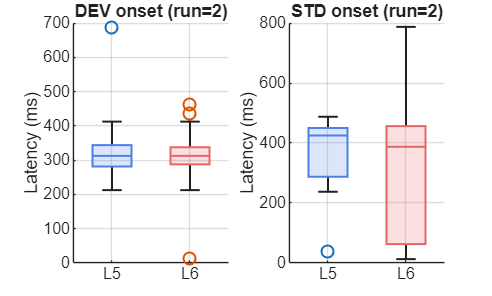


%% -------------------- Visualize onset distributions --------------------
figure('Color','w'); 
subplot(1,2,1);
boxchart_grouped(lat_DEV_CA1, lat_DEV_DG, {'L5','L6'});
title(sprintf('DEV onset (run=%d)', run_len)); ylabel('Latency (ms)');

subplot(1,2,2);
boxchart_grouped(lat_STD_CA1, lat_STD_DG, {'L5','L6'});
title(sprintf('STD onset (run=%d)', run_len)); ylabel('Latency (ms)');


%% -------------------- Console echo of final decisions (h) --------------------
fprintf('\n=== Final decisions (onset comparisons) ===\n');


=== Final decisions (onset comparisons) ===


fprintf('DEV: test=%s, h=%d, p=%.4g, effect=%s=%.3f\n', ...
    stats.DEV.test, stats.DEV.h, stats.DEV.p, stats.DEV.effect_name, stats.DEV.effect);

DEV: test=Rank-sum, h=0, p=0.9702, effect=Cliffs_delta=0.018


fprintf('STD: test=%s, h=%d, p=%.4g, effect=%s=%.3f\n', ...
    stats.STD.test, stats.STD.h, stats.STD.p, stats.STD.effect_name, stats.STD.effect);

STD: test=Rank-sum, h=0, p=0.347, effect=Cliffs_delta=0.280



%% ==================== Helper functions ====================

function [mu, sem] = mean_sem(X, dim)
    if nargin < 2, dim = 1; end
    mu  = mean(X, dim, 'omitnan');
    n   = sum(~isnan(X), dim);
    sd  = std(X, 0, dim, 'omitnan');
    sem = sd;
end

function y = nanmask(mask, val)
    y = nan(size(mask));
    y(mask) = val;
end

function d = cohend(x, y)
    x = x(:); y = y(:);
    nx = sum(~isnan(x)); ny = sum(~isnan(y));
    mx = mean(x,'omitnan'); my = mean(y,'omitnan');
    sx = std(x,0,'omitnan'); sy = std(y,0,'omitnan');
    sp = sqrt(((nx-1)*sx.^2 + (ny-1)*sy.^2) / max(nx+ny-2,1));
    d  = (mx - my) / sp;
end

function [h, p_fdr, crit_p] = fdr_bh(p, q)
    % Benjamini–Hochberg FDR for vector p
    if isrow(p), p = p'; end
    m = sum(~isnan(p));
    [ps, idx] = sort(p, 'ascend', 'MissingPlacement','last');
    thresh = (1:m)'/m * q;
    below  = find(ps <= thresh);
    if isempty(below)
        crit_p = 0; k = 0;
    else
        k = max(below);
        crit_p = ps(k);
    end
    h = false(size(p));
    if k > 0
        h(idx(1:k)) = true;
    end
    p_fdr = p; % (for completeness—uncorrected p's; use h with FDR)
    h = h';
    p_fdr = p_fdr';
end

function lat = halfmax_consecutive_latency(X, t, base_mask, post_onset_ms, run_len)
% X: C x T matrix
% t: 1 x T (ms)
    base_mean = mean(X(:, base_mask), 2, 'omitnan');  % C x 1
    X0 = X - base_mean;                               % baseline-subtracted
    post_mask = t >= post_onset_ms;
    tt = t(post_mask);
    Xp = X0(:, post_mask);
    C = size(Xp,1);
    lat = nan(C,1);
    k = ones(1, run_len);
    for c = 1:C
        r = Xp(c,:);
        if all(isnan(r)), continue; end
        mx = max(r, [], 2, 'omitnan');
        if ~isfinite(mx) || mx==0, continue; end
        thr = mx/2;
        meets = r >= thr;
        win_count = conv(double(meets), k, 'valid');
        start_idx = find(win_count >= run_len, 1, 'first');
        if ~isempty(start_idx)
            lat(c) = tt(start_idx);
        end
    end
end

function summ_line(lbl, v)
    n = sum(~isnan(v));
    m = mean(v,'omitnan');
    s = std(v,'omitnan');
    fprintf('%-7s: %.3f ± %.3f (SEM), n=%d\n', lbl, m, s, n);
end

function out = best_group_test(x, y, label)
% Choose test by normality; report h, p, effect size.
    x = x(~isnan(x)); y = y(~isnan(y));
    nx = numel(x); ny = numel(y);
    % guard
    if nx < 3 || ny < 3
        warning('%s: too few observations (nx=%d, ny=%d). Returning NaNs.', label, nx, ny);
        out = struct('test','NA','h',0,'p',NaN,'effect',NaN,'effect_name','NA');
        return;
    end

    % Normality checks (Lilliefors); fall back if not available
    Lx = try_lillie(x); Ly = try_lillie(y);
    normal = (Lx==0 && Ly==0); % 0 => fail to reject normality

    if normal
        % Welch's t-test (robust to unequal variances)
        [h,p,~,st] = ttest2(x, y, 'Vartype','unequal');
        % Hedges' g (small-sample bias corrected d)
        g = hedges_g(x, y);
        out = struct('test','Welch t','h',h,'p',p,'tstat',st.tstat,'effect',g,'effect_name','Hedges_g');
    else
        % Wilcoxon rank-sum + Cliff's delta
        p = ranksum(x, y);
        h = double(p < 0.05);
        delta = cliffs_delta(x, y);
        out = struct('test','Rank-sum','h',h,'p',p,'effect',delta,'effect_name','Cliffs_delta');
    end

    fprintf('\n[%s] %s: h=%d, p=%.4g, effect %s=%.3f\n', out.test, label, out.h, out.p, out.effect_name, out.effect);
end

function L = try_lillie(v)
    % 0 = normal (fail to reject); 1 = non-normal (reject)
    try
        [L,~] = lillietest(v);
    catch
        % Fallback: Kolmogorov-Smirnov against normal with sample mean/SD
        v = v(:);
        v = (v-mean(v))/std(v);
        [L,~] = kstest(v);
    end
end

function g = hedges_g(x, y)
    x = x(:); y = y(:);
    nx = numel(x); ny = numel(y);
    mx = mean(x); my = mean(y);
    sx = std(x,0); sy = std(y,0);
    sp = sqrt(((nx-1)*sx.^2 + (ny-1)*sy.^2) / max(nx+ny-2,1));
    d  = (mx - my) / sp;
    J  = 1 - (3/(4*(nx+ny)-9)); % small-sample correction
    g  = J * d;
end

function delta = cliffs_delta(x, y)
    % Cliff's delta (probability of superiority - inferiority)
    x = x(:); y = y(:);
    nx = numel(x); ny = numel(y);
    % Efficient pairwise compare
    [sx, ix] = sort(x); %#ok<ASGLU>
    [sy, iy] = sort(y); %#ok<ASGLU>
    i = 1; j = 1; gt = 0; lt = 0;
    while i <= nx && j <= ny
        if sx(i) > sy(j)
            gt = gt + (nx - i + 1);
            j = j + 1;
        elseif sx(i) < sy(j)
            lt = lt + (ny - j + 1);
            i = i + 1;
        else
            % ties: advance both
            ii = i; jj = j;
            while ii <= nx && sx(ii)==sx(i), ii=ii+1; end
            while jj <= ny && sy(jj)==sy(j), jj=jj+1; end
            ties_x = ii - i; ties_y = jj - j;
            % ties contribute neither gt nor lt
            i = ii; j = jj;
        end
    end
    delta = (gt - lt) / (nx*ny);
end

function boxchart_grouped(x, y, labels2)
    % Simple side-by-side box chart
    hold on;
    bx1 = boxchart(ones(size(x)), x); 
    bx2 = boxchart(2*ones(size(y)), y);
    set(bx1,'BoxFaceColor',[0.3 0.5 0.9]); %#ok<*NASGU>
    set(bx2,'BoxFaceColor',[0.9 0.4 0.4]);
    xlim([0.5 2.5]); xticks([1 2]); xticklabels(labels2);
    grid on;
end

%% -------------------- Comparaciones DEV vs STD dentro de región --------------------
% Tests emparejados (canal a canal). Si no hay suficientes pares, cae a no emparejado.
stats_p = struct();

stats_p.CA1 = paired_compare(lat_DEV_CA1, lat_STD_CA1, 'L5: DEV vs STD (paired)');


[Wilcoxon signed-rank] L5: DEV vs STD (paired): h=1, p=0.0007324, effect r (z/sqrt(n))=NaN (n=15)


if stats_p.CA1.used_paired == 0
    stats_p.CA1_unpaired = best_group_test(lat_DEV_CA1, lat_STD_CA1, 'L5: DEV vs STD (unpaired)');
end

stats_p.DG  = paired_compare(lat_DEV_DG,  lat_STD_DG,  'L6: DEV vs STD (paired)');


[Wilcoxon signed-rank] L6: DEV vs STD (paired): h=0, p=0.6875, effect r (z/sqrt(n))=0.068 (n=35)


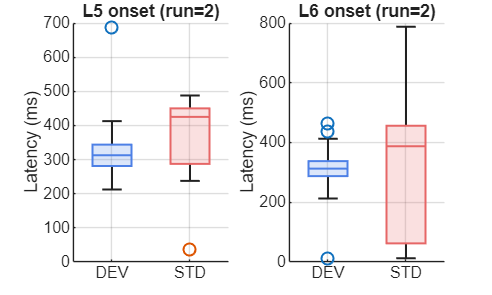

if stats_p.DG.used_paired == 0
    stats_p.DG_unpaired  = best_group_test(lat_DEV_DG,  lat_STD_DG,  'L6: DEV vs STD (unpaired)');
end

%% -------------------- Visualización: DEV vs STD por región --------------------
figure('Color','w'); 
subplot(1,2,1);
boxchart_grouped(lat_DEV_CA1, lat_STD_CA1, {'DEV','STD'});
title(sprintf('L5 onset (run=%d)', run_len)); ylabel('Latency (ms)');

subplot(1,2,2);
boxchart_grouped(lat_DEV_DG, lat_STD_DG, {'DEV','STD'});
title(sprintf('L6 onset (run=%d)', run_len)); ylabel('Latency (ms)');


%% -------------------- Resumen en consola --------------------
fprintf('\n=== Decisiones finales (DEV vs STD por región) ===\n');


=== Decisiones finales (DEV vs STD por región) ===


fprintf('L5 (paired):  test=%s, h=%d, p=%.4g, effect=%s=%.3f\n', ...
    stats_p.CA1.test, stats_p.CA1.h, stats_p.CA1.p, stats_p.CA1.effect_name, stats_p.CA1.effect);

L5 (paired):  test=Wilcoxon signed-rank, h=1, p=0.0007324, effect=r (z/sqrt(n))=NaN


if isfield(stats_p,'CA1_unpaired')
fprintf('L5 (backup):  test=%s, h=%d, p=%.4g, effect=%s=%.3f\n', ...
    stats_p.CA1_unpaired.test, stats_p.CA1_unpaired.h, stats_p.CA1_unpaired.p, ...
    stats_p.CA1_unpaired.effect_name, stats_p.CA1_unpaired.effect);
end

fprintf('L6  (paired):  test=%s, h=%d, p=%.4g, effect=%s=%.3f\n', ...
    stats_p.DG.test, stats_p.DG.h, stats_p.DG.p, stats_p.DG.effect_name, stats_p.DG.effect);

L6  (paired):  test=Wilcoxon signed-rank, h=0, p=0.6875, effect=r (z/sqrt(n))=0.068


if isfield(stats_p,'DG_unpaired')
fprintf('L6  (backup):  test=%s, h=%d, p=%.4g, effect=%s=%.3f\n', ...
    stats_p.DG_unpaired.test, stats_p.DG_unpaired.h, stats_p.DG_unpaired.p, ...
    stats_p.DG_unpaired.effect_name, stats_p.DG_unpaired.effect);
end

%% ==================== NUEVOS helpers ====================
function out = paired_compare(x, y, label)
% Comparación emparejada (canal a canal) con elección de test por normalidad del vector de diferencias.
% Devuelve también un flag 'used_paired' (1 si se pudo, 0 si no).
    % Emparejar solo pares válidos
    x = x(:); y = y(:);
    m = isfinite(x) & isfinite(y);
    x = x(m); y = y(m);
    n = numel(x);
    if n < 3
        warning('%s: muy pocos pares válidos (n=%d).', label, n);
        out = struct('test','NA','h',0,'p',NaN,'effect',NaN,'effect_name','NA','used_paired',0);
        return;
    end

    d = x - y;  % positivo => DEV más temprano que STD si x=DEV
    % Normalidad en las diferencias
    Ld = try_lillie(d);     % 0: normal; 1: no normal

    if Ld==0
        % t de Student pareada
        [h,p,~,st] = ttest(x, y);
        % Efecto: Cohen's dz (sobre diferencias)
        dz = mean(d) / std(d);
        out = struct('test','Paired t','h',h,'p',p,'tstat',st.tstat, ...
                     'effect',dz,'effect_name','Cohen_dz','used_paired',1);
    else % Wilcoxon signed-rank
        [p,~,st] = signrank(x, y);    % entrega z en st.zval (MATLAB >= R2018b)
        h = double(p < 0.05);
        % Efecto robusto: r = z/sqrt(n)
        if isfield(st,'zval') && ~isempty(st.zval)
            r = st.zval / sqrt(n);
        else
            r = NaN;
        end
        out = struct('test','Wilcoxon signed-rank','h',h,'p',p, ...
                     'effect',r,'effect_name','r (z/sqrt(n))','used_paired',1);
    end

    % Echo
    fprintf('\n[%s] %s: h=%d, p=%.4g, effect %s=%.3f (n=%d)\n', ...
        out.test, label, out.h, out.p, out.effect_name, out.effect, n);
end